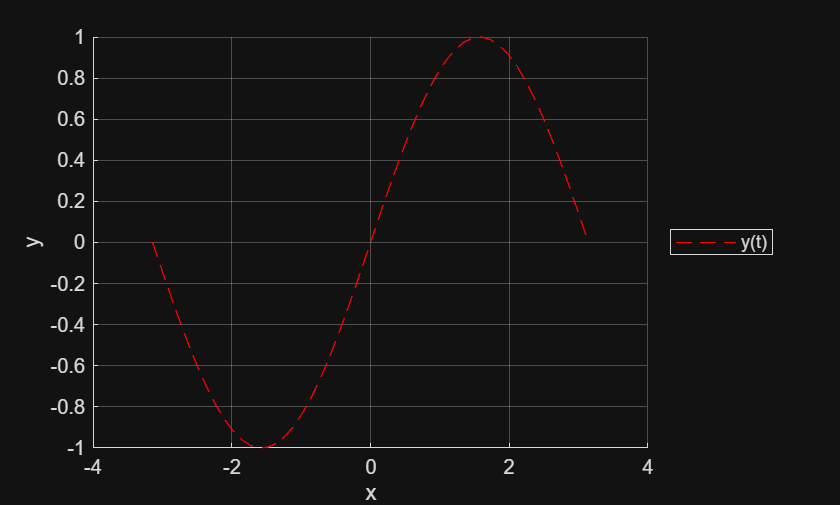

clear
close all
hold on
grid on
t = linspace(-pi,pi, 50);
y = sin(t);
plot(t,y,'r--')
xlabel("x")
ylabel("y")
legend("y(t)",Location="eastoutside")

clear 
close all
grid on
hold on
x = linspace(-pi,pi, 50);
y = (-x).^2 + 9

y =    18.8696   18.0804   17.3240   16.6005   15.9100   15.2523   14.6274   14.0355   13.4765   12.9503   12.4570   11.9966   11.5691   11.1745   10.8128   10.4839   10.1880    9.9249    9.6947    9.4974    9.3330    9.2014    9.1028    9.0370    9.0041    9.0041    9.0370    9.1028    9.2014    9.3330    9.4974    9.6947    9.9249   10.1880   10.4839   10.8128   11.1745   11.5691   11.9966   12.4570   12.9503   13.4765   14.0355   14.6274   15.2523   15.9100   16.6005   17.3240   18.0804   18.8696


y2 = x.^3 -2.*x.^2 - 9

y2 =   -59.7455  -54.5232  -49.6639  -45.1551  -40.9840  -37.1380  -33.6044  -30.3707  -27.4241  -24.7520  -22.3418  -20.1807  -18.2562  -16.5556  -15.0663  -13.7756  -12.6708  -11.7393  -10.9684  -10.3456   -9.8580   -9.4932   -9.2385   -9.0811   -9.0085   -9.0080   -9.0669   -9.1726   -9.3124   -9.4738   -9.6440   -9.8104   -9.9603  -10.0811  -10.1602  -10.1848  -10.1424  -10.0203   -9.8059   -9.4864   -9.0492   -8.4818   -7.7714   -6.9053   -5.8711   -4.6559   -3.2471   -1.6321    0.2017    2.2671


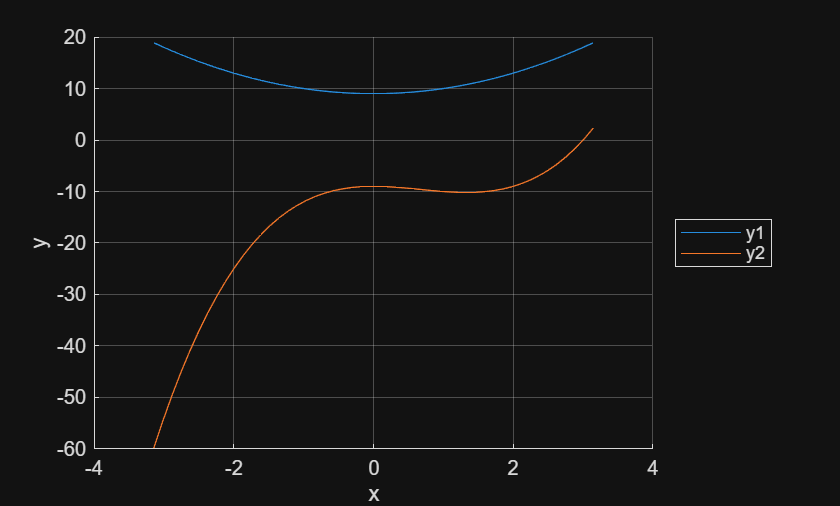

plot(x,y,x,y2)
xlabel("x")
ylabel("y")
legend("y1","y2",Location="eastoutside")

%2 
clear 
close all

M = [10 9 8 9; 9 7 6 8; 9 5 6 4; 10 10 9 10;7 6 9 4; 7 7 8 4]

M =     10     9     8     9
     9     7     6     8
     9     5     6     4
    10    10     9    10
     7     6     9     4
     7     7     8     4



subplot(2,1,1)
b =bar(M','group')

b =   1×6 Bar array:

    Bar    Bar    Bar    Bar    Bar    Bar


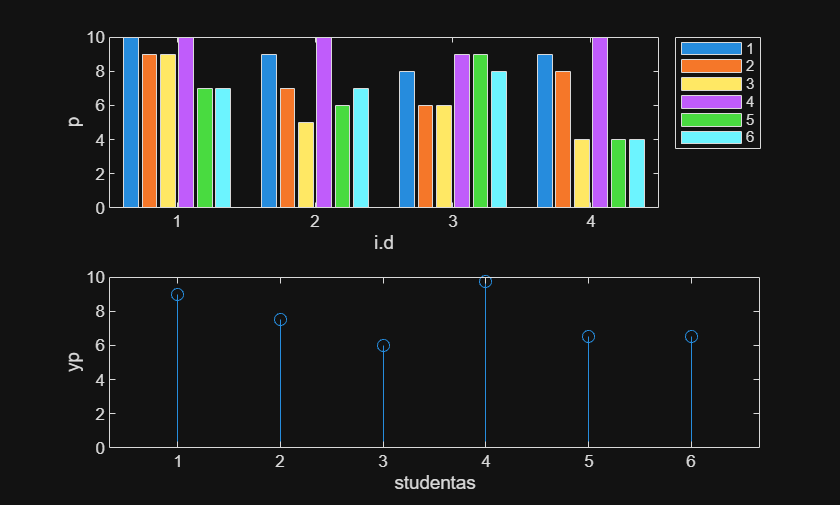

xlabel("i.d")
ylabel("p")
legend("1","2","3","4","5","6",'Location','bestoutside');
s = mean(M,2);
subplot(2,1,2)
stem(s)
xlabel("studentas")
ylabel("yp")

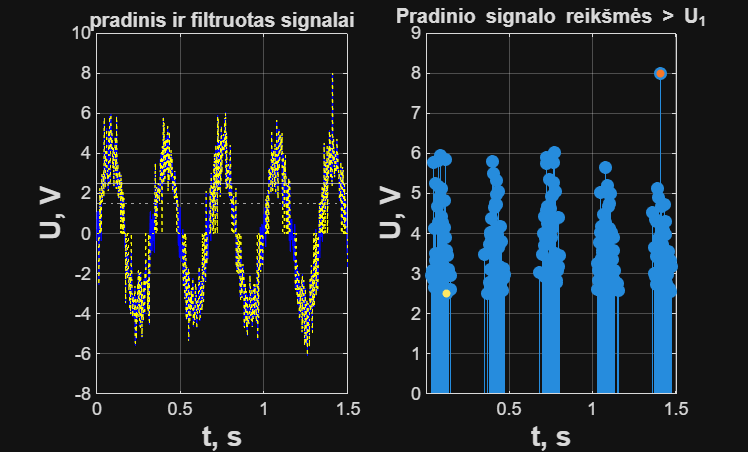

%3
clear
close all
t = 0:0.002:1.5;
A = 4;
f = 3;
q = 1;
U1 = 2.5;
U2 = 1.5;

sc = A*sin(2*pi*f*t);
n = q * randn(size(t));
s = sc + n;

s2 = s;
s2(abs(s2) < U2) = 0;  

figure;
subplot(1,2,1)
plot(t,s,'b-')
hold on;
plot(t,s2,'y:')
yline(U1)
yline(U2, ":")
grid on
title("pradinis ir filtruotas signalai")
xlabel('t, s', 'FontSize',14, 'FontWeight','bold')
ylabel('U, V', 'FontSize',14, 'FontWeight','bold')

idx = s > U1;
t_sel = t(idx);
s_sel = s(idx);

subplot(1,2,2)
stem(t_sel, s_sel, 'filled'); hold on
[maxVal, maxI] = max(s_sel);
[minVal, minI] = min(s_sel);
plot(t_sel(maxI), maxVal,'.', 'MarkerSize',12, 'MarkerFaceColor','r');
plot(t_sel(minI), minVal, '.','MarkerSize',12, 'MarkerFaceColor','g');
xlabel('t, s', 'FontSize',14, 'FontWeight','bold')
ylabel('U, V', 'FontSize',14, 'FontWeight','bold')
title('Pradinio signalo reikšmės > U_1')

grid on